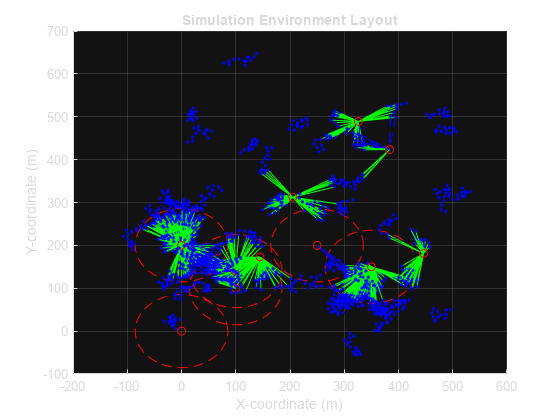

% Main script starts here
% Step 1: Define Base Stations and Mobile Devices
% ------------------------------------------------

% Define the positions of 5 base stations randomly
numBaseStations = 5;
areaWidth = 500;
areaHeight = 500;
baseStationPositions = rand(numBaseStations, 2) .* [areaWidth, areaHeight];

% Define the number of mobile devices
numMobileDevices = 50;

% Generate random locations for mobile devices
mobileDeviceLocations = rand(numMobileDevices, 2) .* [areaWidth, areaHeight];

% Visualize the layout
figure;
set(gcf, 'Color', 'w'); % Set figure background to white
scatter(baseStationPositions(:,1), baseStationPositions(:,2), 'ro', 'DisplayName', 'Base Stations');
hold on;
scatter(mobileDeviceLocations(:,1), mobileDeviceLocations(:,2), 'b.', 'DisplayName', 'Mobile Devices');
xlabel('X-coordinate (m)');
ylabel('Y-coordinate (m)');
title('Simulation Environment Layout');

% Step 3: Base Station Parameters
% --------------------------------
% Define 5G simulation parameters
baseStationParams = struct('transmitPower', 30, ...
                           'antennaGain', 15, ...
                           'frequency', 28e9, ...
                           'MIMO', true);

% Calculate coverage radius for base stations
coverageRadius = calculateCoverageRadius(baseStationParams);

% Define coverage areas for base stations
baseStationCoverage = defineCoverageAreas(baseStationPositions, coverageRadius);

% Visualize coverage areas
for i = 1:length(baseStationCoverage)
    plotCircle(baseStationCoverage(i).center, baseStationCoverage(i).radius);
end

% Step 4: Mobile Device Parameters
% ---------------------------------
mobilityPattern = 'randomWalk'; % Mobility pattern

% Step 5: Simulate Mobility
% --------------------------
numSteps = 50; % Number of simulation steps

% Simulate mobility of mobile devices
for t = 1:numSteps
    % Update positions of mobile devices
    if strcmp(mobilityPattern, 'randomWalk')
        % Random walk model
        stepSize = 10; % Step size in meters
        directions = rand(numMobileDevices, 1) * 2 * pi; % Random directions
        mobileDeviceLocations(:, 1) = mobileDeviceLocations(:, 1) + stepSize * cos(directions);
        mobileDeviceLocations(:, 2) = mobileDeviceLocations(:, 2) + stepSize * sin(directions);
    end
    
    % Perform handover and dual connectivity
    for i = 1:numMobileDevices
        devicePos = mobileDeviceLocations(i, :);
        newBS = performHandover(devicePos, baseStationPositions, baseStationParams);
        [primaryBS, secondaryBS] = performDualConnectivity(devicePos, baseStationPositions, baseStationParams);
        
        % Update connection status (for visualization purposes)
        % For example, you can plot the lines indicating connections
        if primaryBS > 0
            plot([devicePos(1), baseStationPositions(primaryBS, 1)], ...
                 [devicePos(2), baseStationPositions(primaryBS, 2)], 'g-');
        end
        if secondaryBS > 0
            plot([devicePos(1), baseStationPositions(secondaryBS, 1)], ...
                 [devicePos(2), baseStationPositions(secondaryBS, 2)], 'b--');
        end
    end
    
    % Update the plot
    scatter(baseStationPositions(:,1), baseStationPositions(:,2), 'ro');
    hold on;
    scatter(mobileDeviceLocations(:,1), mobileDeviceLocations(:,2), 'b.');
    xlabel('X-coordinate (m)');
    ylabel('Y-coordinate (m)');
    title('Simulation Environment Layout');
    drawnow;
    grid on;
end


% Define the functions below


function radius = calculateCoverageRadius(baseStationParams)
    % Example calculation using Friis transmission equation (simplified)
    % Assuming free-space path loss model for this example
    % Convert transmit power from dBm to Watts
    transmitPowerWatts = 10^((baseStationParams.transmitPower - 30) / 10);
    % Convert frequency to Hz
    frequencyHz = baseStationParams.frequency;
    % Speed of light
    c = 3e8;
    % Path loss at reference distance (1 meter)
    pathLossRef = (4 * pi * 1 * frequencyHz / c)^2;
    % Receiver sensitivity (in Watts) -- this should be defined based on your system
    receiverSensitivityWatts = 1e-10;
    % Coverage radius calculation
    radius = sqrt(transmitPowerWatts / (receiverSensitivityWatts * pathLossRef));
end

function coverage = defineCoverageAreas(baseStationLocations, coverageRadius)
    numBaseStations = size(baseStationLocations, 1);
    coverage(numBaseStations) = struct('center', [], 'radius', []);
    for i = 1:numBaseStations
        coverage(i).center = baseStationLocations(i, :);
        coverage(i).radius = coverageRadius;
    end
end

function plotCircle(center, radius)
    theta = linspace(0, 2*pi, 100);
    x = center(1) + radius * cos(theta);
    y = center(2) + radius * sin(theta);
    plot(x, y,    'r--');
end

function newBS = performHandover(devicePos, baseStationPositions, baseStationParams)
    numBaseStations = size(baseStationPositions, 1);
    coverageRadius = calculateCoverageRadius(baseStationParams);
    newBS = -1;
    minDistance = inf;
    for i = 1:numBaseStations
        distance = norm(devicePos - baseStationPositions(i, :));
        if distance < coverageRadius && distance < minDistance
            minDistance = distance;
            newBS = i;
        end
    end
end

function [primaryBS, secondaryBS] = performDualConnectivity(devicePos, baseStationPositions, baseStationParams)
    numBaseStations = size(baseStationPositions, 1);
    coverageRadius = calculateCoverageRadius(baseStationParams);
    distances = zeros(numBaseStations, 1);
    for i = 1:numBaseStations
        distances(i) = norm(devicePos - baseStationPositions(i, :));
    end
    [sortedDistances, sortedIndices] = sort(distances);
    primaryBS = -1;
    secondaryBS = -1;
    if sortedDistances(1) < coverageRadius
        primaryBS = sortedIndices(1);
    end
    if length(sortedDistances) > 1 && sortedDistances(2) < coverageRadius
        secondaryBS = sortedIndices(2);
    end
end

